# Testing del metodo di Jacobi

### Casi d'uso

Si testa il software su matrici sparse di notevoli dimensioni, generate usando funzioni Matlab non singolari e ben condizionate. Si illustra, attraverso grafico, la struttura delle matrici di test. Un primo esempio di matrice ben condizionata:

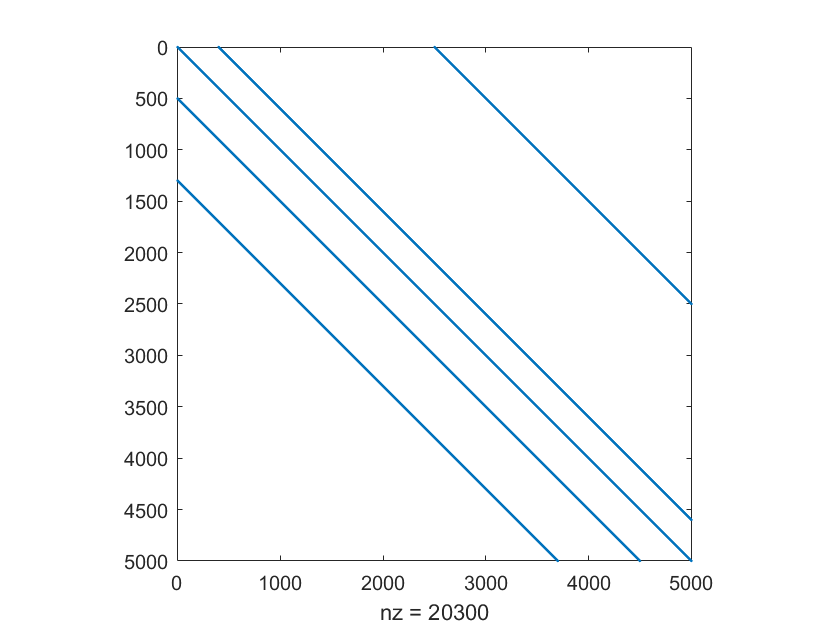

n = 5000;
e = ones(n,1);
Z = spdiags([e 3*e 15*e -e e], [-1300 -500 0 400 2500], n, n);
spy(Z)

b = Z*e;
c = condest(Z)

c = 2.2693

[sol, niter] = Jacobi(Z, b)

sol =     1.0000
    1.0000
    1.0000
    1.0000
    1.0000
    1.0000
    1.0000
    1.0000
    1.0000
    1.0000


niter = 11

Esempio d'uso nel caso in cui l'utente specifichi il valore di tolleranza:

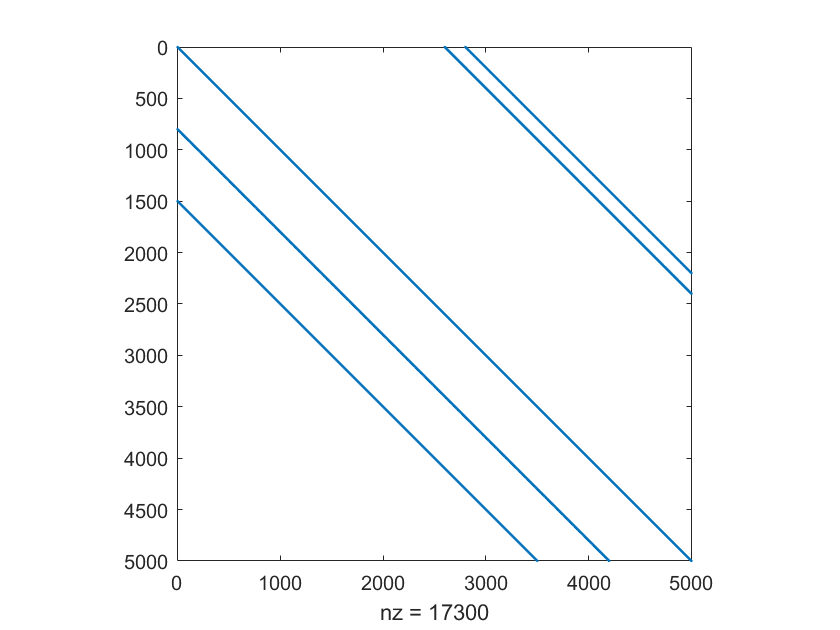

n = 5000;
e = ones(n,1);
Z = spdiags([e 6*e 10*e -e e], [-1500 -800 0 2600 2800], n, n);
spy(Z)

b = Z*e;
c = condest(Z)

c = 6.3495

[sol, niter] = Jacobi(Z, b, 10^-9)

sol =     1.0000
    1.0000
    1.0000
    1.0000
    1.0000
    1.0000
    1.0000
    1.0000
    1.0000
    1.0000


niter = 42

Esempio d'uso nel caso in cui l'utente specifichi il valore di tolleranza e il numero massimo di iterazioni:

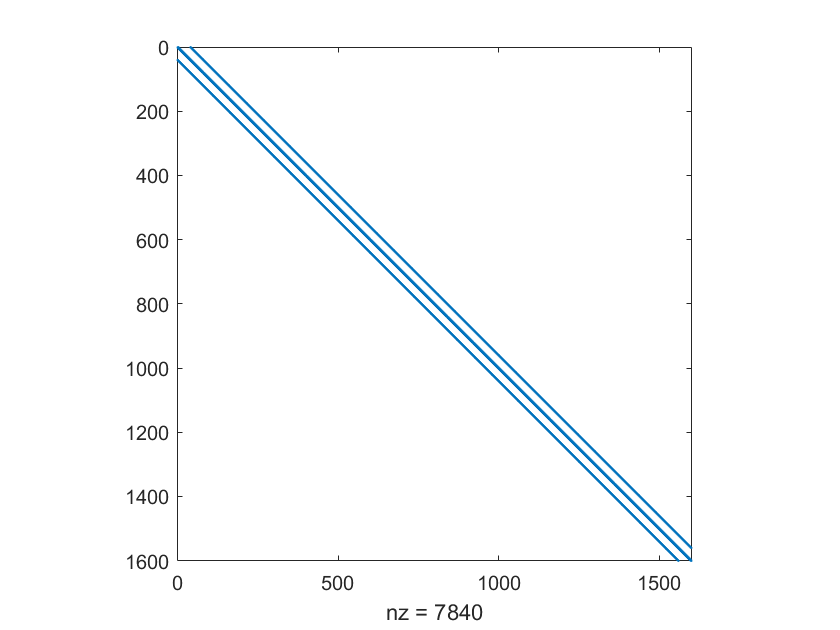

X = gallery('poisson',40);
spy(X)

c = condest(X)

c = 989.2690

x = ones(1600,1);
b = X*x;
[sol, niter] = Jacobi(X,b,10^-6,3000)

sol =     1.0000
    1.0000
    1.0000
    1.0000
    1.0000
    1.0000
    1.0000
    1.0000
    1.0000
    1.0000


niter = 2881

### Casi di errore

Utilizziamo la matrice sparsa di Toeppen che presenta elementi nulli sulla diagonale. Per questo tipo di matrici, il metodo di Jacobi non è definito.

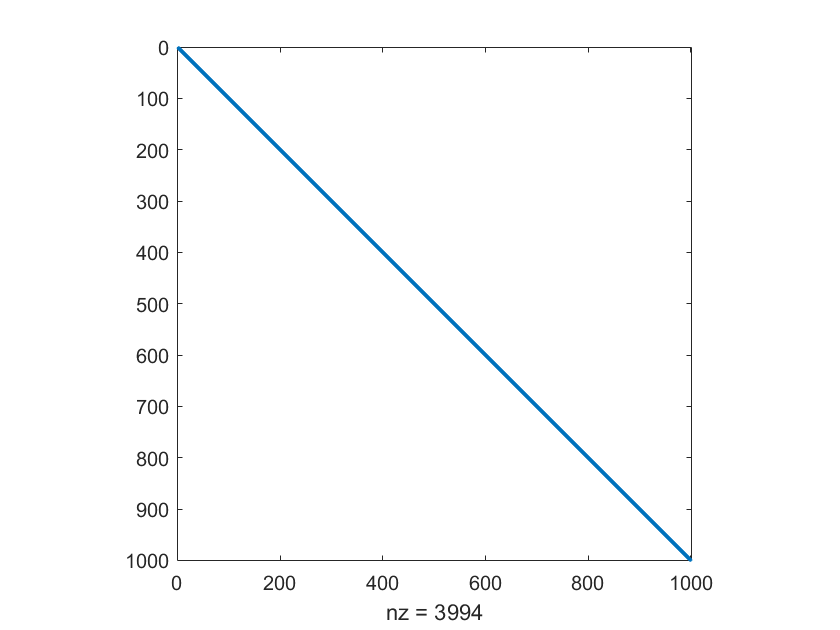

T = gallery('toeppen',1000);
spy(T)

b = T*ones(1000,1);
[sol, niter] = Jacobi(T,b)

Error using Jacobi (line 23)
La matrice A ha elementi nulli sulla diagonale. Riordinare la matrice e rieseguire l'algoritmo.

Caso in cui la matrice in ingresso è vuota.

A = [];
A = sparse(A);
[sol, niter] = Jacobi(A,b);

Caso in cui il vettore in ingresso è vuoto.

A = spdiags([e 3*e 15*e -e e], [-1300 -500 0 400 2500], 50, 50);
b = [];
[sol, niter] = Jacobi(A,b);

Caso in cui la matrice A è di tipo sparse.

A = [0 0 3; 1 0 0; 0 0 8];
[sol, niter] = Jacobi(A,b);

Caso in cui A è una matrice quadrata.

A = sparse(10, 12);
[sol, niter] = Jacobi(A,b);

Caso in cui b non è un vettore ma un carattere.

A = spdiags([e 3*e 15*e -e e], [-1300 -500 0 400 2500], 50, 50);
b = 'c';
[sol, niter] = Jacobi(A,b);

Caso in cui b non è un vettore ma una table.

A = spdiags([e 3*e 15*e -e e], [-1300 -500 0 400 2500], 50, 50);
b = table(54,75);
[sol, niter] = Jacobi(A,b);

Caso in cui b non è un vettore ma una struct.

A = spdiags([e 3*e 15*e -e e], [-1300 -500 0 400 2500], 50, 50);
b.Field = 7;
[sol, niter] = Jacobi(A,b);

Caso in cui b non è un vettore numerico.

A = spdiags([e 3*e 15*e -e e], [-1300 -500 0 400 2500], 3, 3);
b = ['c','d','e'];
[sol, niter] = Jacobi(A,b);

Caso in cui b non rispetta le dimensioni di A.

A = spdiags([e 3*e 15*e -e e], [-1300 -500 0 400 2500], 50, 50);
b = rand(40,1);
[sol, niter] = Jacobi(A,b);

### Test di accuratezza

Nella seguente sezione si confrontano i risultati ottenuti mediante la funzione di Jacobi con le soluzioni imposte

n = 5000;
e = ones(n,1);
Z = spdiags([e 3*e 15*e -e e], [-1300 -500 0 400 2500], n, n);
spy(Z);
b = Z*e;
c = condest(Z)
[sol, niter, res] = Jacobi(Z, b)
err = norm(e-sol)/norm(sol)

Aumentiamo il numero di cifre significative richieste:

[sol, niter, res] = Jacobi(Z, b, 10^-13)
err = norm(e-sol)/norm(sol)

### Velocità di convergenza

Nei paragrafi precedenti è stato già notato come, all'aumentare del condizionamento e del raggio spettrale, la function converga in un numero di iterazioni maggiore. Mostriamo qui alcuni esempi.

e = ones(4000,1);
Z = spdiags([e 6*e 10*e -e e], [-1500 -800 0 2400 2800], 4000, 4000);
spy(Z)
b = Z*e;
c = condest(Z)
[sol, niter] = Jacobi(Z, b, 10^-7)
A = gallery('poisson',25);
spy(A);
c = condest(A)
x = ones(625,1);
b = A*x;
[sol, niter] = Jacobi(A, b, 10^-7,1800)

La prima esecuzione converge in 27 iterazioni con precisione a 7 cifre. La seconda esecuzione, a parità di cifre significative richieste, converge in 1597 iterazioni. Ciò trova una spiegazione teorica nell'aumento del raggio spettrale della matrice B calcolata dal metodo di Jacobi.

### Casi di warning

Caso in cui il parametro TOL è un carattere.

A = spdiags([e 3*e 15*e -e e], [-1300 -500 0 400 2500], 50, 50);
b = rand(50,1);
[sol, niter] = Jacobi(A,b,'c');

Caso in cui il parametro TOL è minore di eps.

A = spdiags([e 3*e 15*e -e e], [-1300 -500 0 400 2500], 50, 50);
b = rand(50,1);
[sol, niter] = Jacobi(A,b,eps/2);

Caso in cui il parametro TOL non è finito.

A = spdiags([e 3*e 15*e -e e], [-1300 -500 0 400 2500], 50, 50);
b = rand(50,1);
[sol, niter] = Jacobi(A,b,inf);

Caso in cui è specificato anche il quarto parametro ma TOL non è reale.

A = spdiags([e 3*e 15*e -e e], [-1300 -500 0 400 2500], 50, 50);
b = rand(50,1);
[sol, niter] = Jacobi(A,b,5i,600);

Caso in cui il parametro MAXITER non è finito.

A = spdiags([e 3*e 15*e -e e], [-1300 -500 0 400 2500], 50, 50);
b = rand(50,1);
[sol, niter] = Jacobi(A,b,10^-9,inf);

Caso in cui il parametro MAXITER non è uno scalare.

A = spdiags([e 3*e 15*e -e e], [-1300 -500 0 400 2500], 50, 50);
b = rand(50,1);
[sol, niter] = Jacobi(A,b,10^-9,[1 2 3]);

Caso in cui il parametro MAXITER non è reale.

A = spdiags([e 3*e 15*e -e e], [-1300 -500 0 400 2500], 50, 50);
b = rand(50,1);
[sol, niter] = Jacobi(A,b,10^-9,3i);

Potrebbe capitare che il numero di iterazioni massimo non sia sufficiente per ottenere il numero di cifre significative desiderato. Mostriamo di seguito alcuni esempi:

X = gallery('poisson',45);
c = condest(X)
x = ones(2025,1);
b = X*x;
[sol, niter] = Jacobi(X,b,10^-6,1000)
[sol, niter] = Jacobi(X,b,10^-6,4000)
err = norm(x-sol)/norm(sol)

In questo caso, dato che il primo numero massimo di iterazioni è stato impostato a 1000, la function stampa un messaggio di warning specificando che il risultato potrebbe non soddisfare l'accuratezza richiesta. Se si aumenta tale parametro, la function converge al risultato con accuratezza corretta.

Il prossimo esempio, invece, mostra una matrice malcondizionata e la matrice B calcolata dal metodo ha raggio spettrale uguale a 1. In questo caso, il metodo iterativo di Jacobi non converge.

D = gallery('dorr',50);
spy(D)
c = condest(D)
e = ones(50,1);
b = D*e;
[sol, niter] = Jacobi(D,b,10^-6,30000)
err = norm(e-sol)/norm(sol)

Caso in cui diagonale non è strettamente dominante e buon condizionamento (vale per tutti i tol) NON CONVERGE anche con Tol = 10^-15 e aumentando le iterazioni.

W = spdiags([e 5*e 2*e -e e], [-1300 -500 0 400 2500], n, n);
spy(W);

b = W*e;
[sol4, niter4] = Jacobi(W,b,10^(-15));